# Problem 1

## Import CSV File

% Fold 1
Fold1 = readtable("Homework05_KNN_Problem_1/Fold1.csv");
Fold1.Properties.VariableNames = ["Y", "X1", "X2"]

Fold1 = 100×3 table
    Y       X1           X2    
    _    _________    _________

    1      0.44915      0.43686
    1     0.037043      0.33935
    1      0.28287      0.39069
    0     -0.40339     -0.44494
    1      0.12257      0.12646
    0     -0.18587     -0.48984
    1      0.35116      0.34661
    0     -0.26973     -0.47737
    0     -0.25014    -0.035202
    0     -0.16709     -0.08062
    0     -0.47403     -0.16403
    1     0.034489      0.14245
    1     0.082435      0.45141
    0     -0.45141      -0.1332
    1      0.02727      0.10287
    0    -0.025305     -0.36653


% Fold 2
Fold2 = readtable("Homework05_KNN_Problem_1/Fold2.csv");
Fold2.Properties.VariableNames = ["Y", "X1", "X2"]

Fold2 = 100×3 table
    Y       X1            X2    
    _    _________    __________

    1      0.48512      -0.13156
    0     -0.10335       0.40376
    0     -0.35659    -0.0067007
    0    -0.078828     -0.013261
    1      0.44338      -0.31948
    0     -0.24506       0.26603
    1      0.45796      -0.41717
    0     -0.35322       0.48392
    0     -0.11715       0.32397
    1     0.055064      -0.38991
    1      0.15591      -0.23757
    1     0.073708      -0.28394
    0     -0.39044       0.45154
    1      0.16014     -0.093526
    1      0.47372      -0.25446
    1      0.14822      -0.48759


## Import KNN-Clasifier

MDL = fitcknn(Fold1,"Y", "NumNeighbors",5)

MDL =   ClassificationKNN
           PredictorNames: {'X1'  'X2'}
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: [0 1]
           ScoreTransform: 'none'
          NumObservations: 100
                 Distance: 'euclidean'
             NumNeighbors: 5


  Properties, Methods


[label, score, cost] = predict(MDL,Fold2)

label =      1
     1
     0
     0
     1
     0
     1
     1
     1
     0


score =          0    1.0000
         0    1.0000
    1.0000         0
    1.0000         0
         0    1.0000
    0.6000    0.4000
         0    1.0000
         0    1.0000
         0    1.0000
    1.0000         0


cost =     1.0000         0
    1.0000         0
         0    1.0000
         0    1.0000
    1.0000         0
    0.4000    0.6000
    1.0000         0
    1.0000         0
    1.0000         0
         0    1.0000


## Create ROC Curve

score = score(:,1)

score =          0
         0
    1.0000
    1.0000
         0
    0.6000
         0
         0
         0
    1.0000


[x,y] = perfcurve(Fold2.Y, score, 1)

x =          0
    0.3400
    0.4000
    0.4800
    0.5200
    0.6800
    1.0000


y =          0
    0.3000
    0.3400
    0.4000
    0.4400
    0.5600
    1.0000


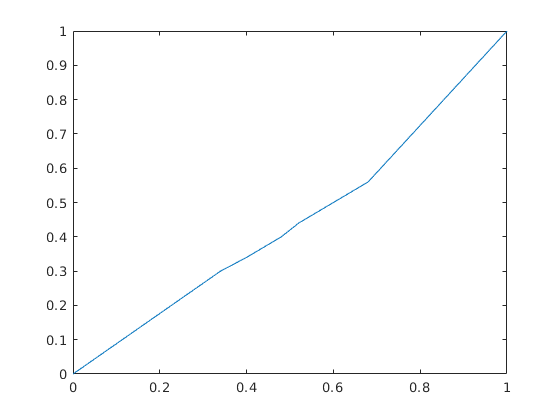

plot(x,y)